# Spline cúbico, Matricial x 4 Puntos (theta1)

% puntos para spline, en tiemp de 1 a 4
Puntos=([(1:4)',theta1'])';
Puntos=Puntos(:);

## Construcción de matríz característica

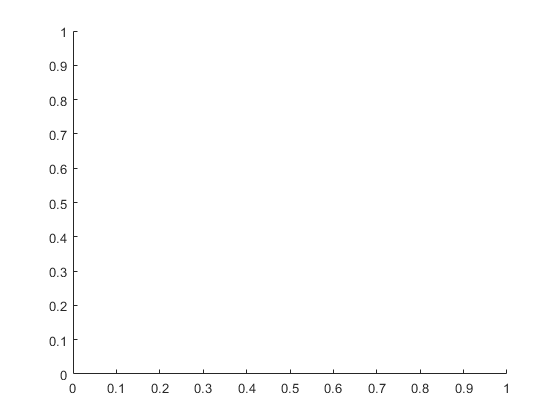

A0=[Puntos(1)^3,Puntos(1)^2,Puntos(1),1;Puntos(3)^3,Puntos(3)^2,Puntos(3),1];
A1=[Puntos(3)^3,Puntos(3)^2,Puntos(3),1;Puntos(5)^3,Puntos(5)^2,Puntos(5),1];
A2=[Puntos(5)^3,Puntos(5)^2,Puntos(5),1;Puntos(7)^3,Puntos(7)^2,Puntos(7),1];

A11=[3*Puntos(3)^2,2*Puntos(3),1,0,-3*Puntos(3)^2,-2*Puntos(3),-1,0];
A12=[3*Puntos(5)^2,2*Puntos(5),1,0,-3*Puntos(5)^2,-2*Puntos(5),-1,0];

A111=[6*Puntos(3),2,0,0,-6*Puntos(3),-2,0,0];
A222=[6*Puntos(5),2,0,0,-6*Puntos(5),-2,0,0];


A=[A0,0*A0,0*A0;0*A0,A1,0*A0;A0*0,A0*0,A2;A11,0,0,0,0;0,0,0,0,A12;A111,0,0,0,0;0,0,0,0,A222];

A=[A;3*Puntos(1)^2,2*Puntos(1),1,0,0,0,0,0,0,0,0,0];
A=[A;0,0,0,0,0,0,0,0,3*Puntos(7)^2,2*Puntos(7),1,0];
b=[Puntos(2);Puntos(4);Puntos(4);Puntos(6);Puntos(6);Puntos(8);0;0;0;0;0;0];
hold off

solv=A\b;


## Graficar y obtener tramos de polinomio

Para cada tramo encontrado en la solución, escribir el polinomio

entre los dos puntos del tramo correspondiente, con separacion 0.05

x=Puntos(1):0.05:(Puntos(3));
y=solv(1)*x.^3+solv(2)*x.^2+solv(3)*x+solv(4);
plot(x,y)
hold on

x1=Puntos(3):0.05:Puntos(5);
y1=solv(5)*x1.^3+solv(6)*x1.^2+solv(7)*x1+solv(8)

y1 =    1.344388029422404   1.243558581671849   1.109890119956148   0.947328389240468   0.759819134490201   0.551308100670738   0.325741032747331   0.087063675685286  -0.160778225549976  -0.413838925993204  -0.668172680679007  -0.919833744642162  -1.164876372917220  -1.399354820538903  -1.619323342541904  -1.820836193960830  -1.999947629830487  -2.152711905185399  -2.275183275060371  -2.363415994489870  -2.413464318508815


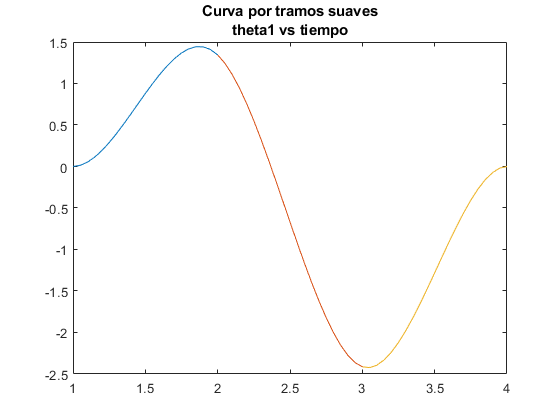

plot(x1,y1)
 
x2=Puntos(5):0.05:Puntos(7);
y2=solv(9)*x2.^3+solv(10)*x2.^2+solv(11)*x2+solv(12);

plot(x2,y2)
title({'Curva por tramos suaves';'theta1 vs tiempo'})

X1=[x,x1(2:end-1),x2];
Y1=[y,y1(2:end-1),y2];
hold off

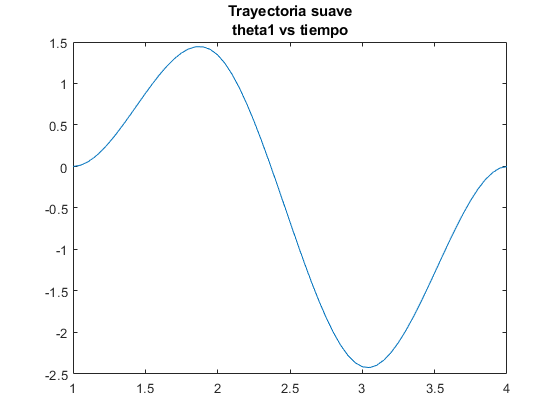

plot(X1,Y1)
title({'Trayectoria suave';'theta1 vs tiempo'})

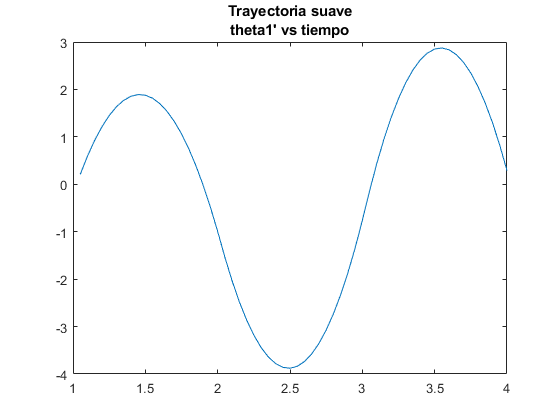


factor=length((1:4)')/length(Y1);
plot(X1(2:end),diff(Y1)/factor)
title({'Trayectoria suave';"theta1' vs tiempo"})

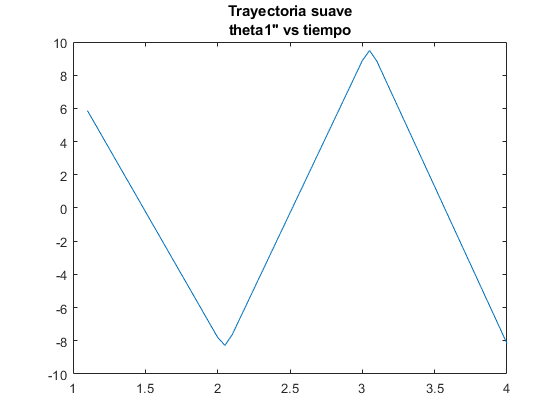


plot(X1(3:end),diff(diff(Y1))/(factor^2))
title({'Trayectoria suave';"theta1'' vs tiempo"})




% Programado por: Alfredo José Maussa Caballero.